
clc; clear all; close all;

s=tf('s');
gp = 1.7342*(-3.33*s+1)*(-5.02*s+1)*exp(-1.25*s)/((10.2*s+1)*(4.5*s+1)^2)

gp =
 
                   28.99 s^2 - 14.48 s + 1.734
  exp(-1.25*s) * --------------------------------
                 206.5 s^3 + 112 s^2 + 19.2 s + 1
 
Continuous-time transfer function.
Model Properties


gptilde = 1.75*(-3*s+1)*(-5*s+1)*exp(-1.25*s)/((10*s+1)*(4*s+1)^2)

gptilde =
 
                   26.25 s^2 - 14 s + 1.75
  exp(-1.25*s) * ---------------------------
                 160 s^3 + 96 s^2 + 18 s + 1
 
Continuous-time transfer function.
Model Properties


INV = (3*s+1)*(5*s+1)\((10*s+1)*(4*s+1)^2)

INV =
 
  160 s^3 + 96 s^2 + 18 s + 1
  ---------------------------
       15 s^2 + 8 s + 1
 
Continuous-time transfer function.
Model Properties


INV = INV/(dcgain(INV)*dcgain(gptilde));


## Gamma = 0

Lambda = 1

Lambda = 1

F = 1/(Lambda*s+1)^1; % n >= 0 + deg(INV) = 0+1 =1
q = INV*F;
C = q/(1-q*gptilde);
IMC_CL = feedback(C*gp,1)

IMC_CL =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12       x13
   x1     -1.533      -0.6   -0.2667         0         0         0         0         0         0         4         0         0         0
   x2          1         0         0         0         0         0         0         0         0         0         0         0         0
   x3          0      0.25         0         0         0         0         0         0         0         0         0         0         0
   x4          0         0         0    -2.133    -1.633   -0.6054   -0.2342     -0.09  -0.05333         1         0         0         0
   x5          0         0         0         1         0         0         0         0         0         0         0         0         0
   x6          0         0         0         0         1         0         0         0         0         0         0         0         0
   x7          0       

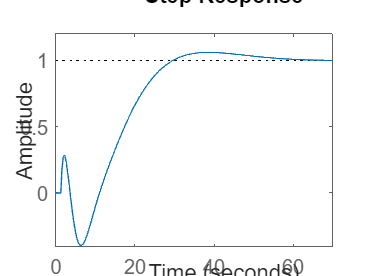

step(IMC_CL); hold on

## Gamma != 0

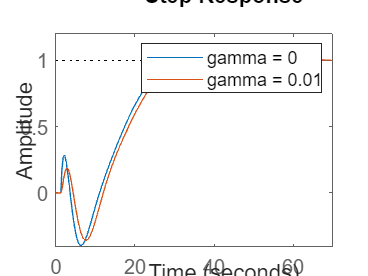

Lambda2 = 1;
gamma2 = 0.01;
F = (gamma2*s+1)/(Lambda2*s+1)^2; % n >= 1 + deg(INV) = 0+1 =1
q = INV*F;
C = q/(1-q*gptilde);
IMC_CL = feedback(C*gp,1);
step(IMC_CL);
legend('gamma = 0','gamma = 0.01')